clc; 
close all;

### Specifications Given

A = 2;               % my index no. is 180220A. You can change these values.
B = 2; 
C = 0; 

A_p = 0.03+0.01*A;   %dB max passband ripple 
A_a = 45+B;          %dB min stopband attenuation 
wp1 = C*100+300;     %rad/s lower passband edge 
wp2 = C*100+700;     %rad/s upper passband edge 
wa1 = C*100+150;     %rad/s lower stopband edge 
wa2 = C*100+800;     %rad/s upper stopband edge 
ws = 2*(C*100+1200); %sampling frequency

### Derived Specifications

bt1 = wp1-wa1;       %lower transition width 
bt2 = wa2-wp2;       % upper transisiton width 
bt = min(bt1,bt2);   %critical transition width 
wc1 = wp1-bt/2;      % lower cutoff frequency 
wc2 = wp2+bt/2;      % upper cutoff frequency 
T = 2*pi/ws;         % sampling period

### Kaiser Window Parameters

deltaP = (10^(0.05*A_p) - 1)/ (10^(0.05*A_p) + 1);   % calculating delta 
deltaA = 10^(-0.05*A_a); 
delta = min(deltaP,deltaA); 

Aa = -20*log10(delta);                               % Actual stopband attenuation 

if Aa<=21                                            % Calculating alpha 
    alpha = 0; 
elseif Aa>21 && Aa<= 50 
    alpha = 0.5842*(Aa-21)^0.4 + 0.07886*(Aa-21); 
else 
    alpha = 0.1102*(Aa-8.7); 
end 

if Aa <= 21                                          % Calculating D 
    D = 0.9222; 
else 
    D = (Aa-7.95)/14.36; 
end

if mod(ceil((ws*D)/bt+1),2) == 0                     %Choosing the Lowest Odd Value of N 
    N = ceil((ws*D)/bt+1) + 1; 
else 
    N = ceil((ws*D)/bt+1); 
end 
n = -(N-1)/2:1:(N-1)/2;                              % length of the filter 
beta = alpha*sqrt(1-(2*n/(N-1)).^2);

### Generating I(alpha) and I(beta)

Ibeta = 0; 
Ialpha = 0; 
bessellimit = 50; 

for k = 1 : 1 : bessellimit 
    Ibeta = Ibeta + ((1/factorial(k))*(beta/2).^k).^2; 
    Ialpha = Ialpha + ((1/factorial(k))*(alpha/2)^k)^2; 
end 

Ibeta = Ibeta + ones(1,numel(Ibeta)); 
Ialpha = Ialpha + ones(1,numel(Ialpha));

### Obtaining Kaiser Window

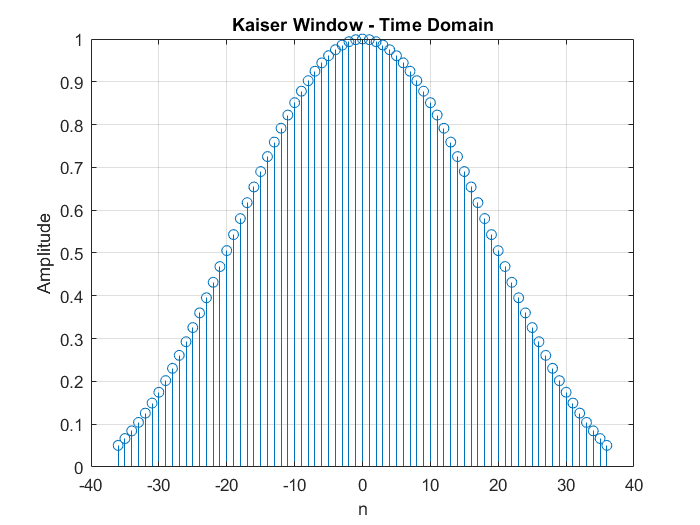

wknt = Ibeta/Ialpha; 
figure 
stem(n,wknt) 
xlabel('n') 
ylabel('Amplitude') 
title('Kaiser Window - Time Domain'); 
grid on;

### Generating Impulse Response

nleft = -(N-1)/2:-1; 
hntleft = 1./(nleft*pi).*(sin(wc2*nleft*T)-sin(wc1*nleft*T)); 
nright = 1:(N-1)/2; 
hntright = 1./(nright*pi).*(sin(wc2*nright*T)-sin(wc1*nright*T)); 
hnt0 = 2*(wc2-wc1)/ws; 
hnt = [hntleft,hnt0,hntright];

### Applying the window to the filter

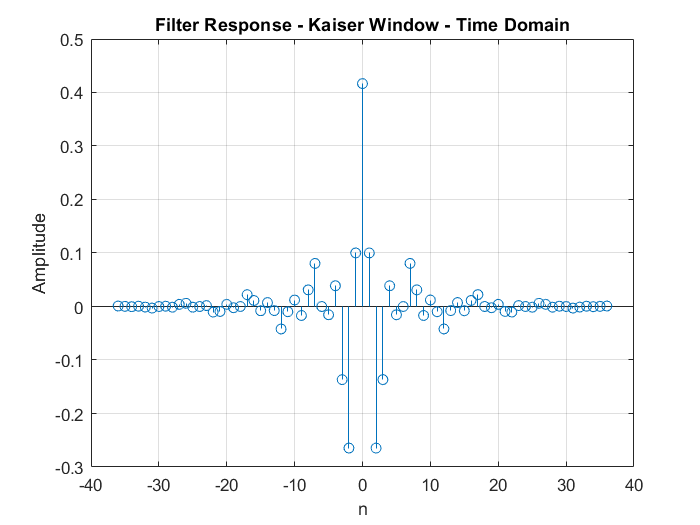

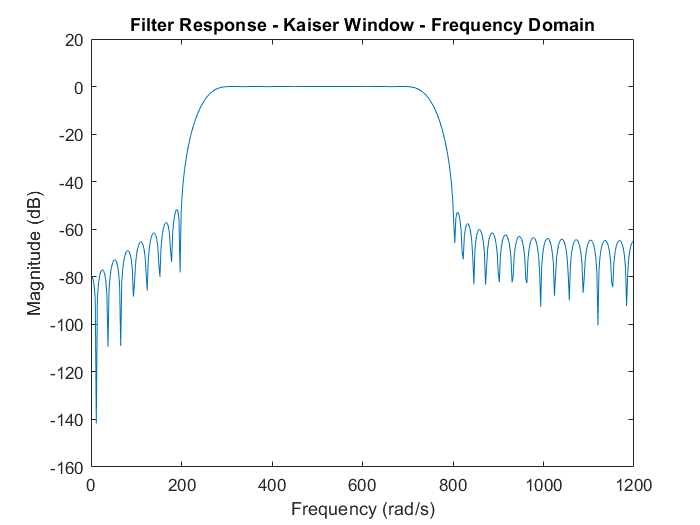

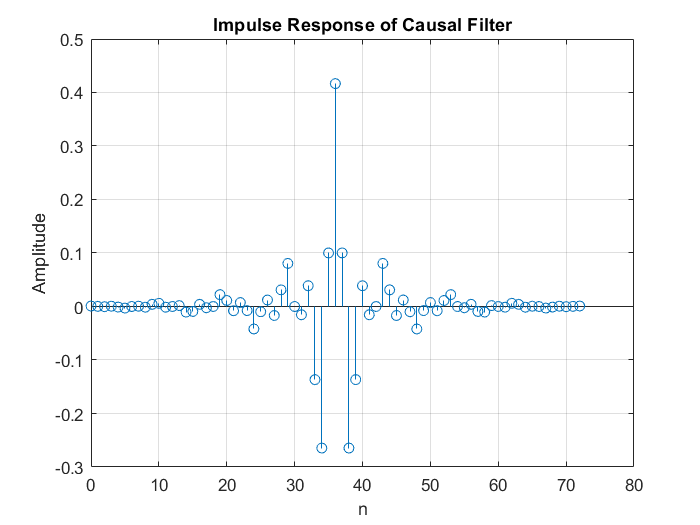

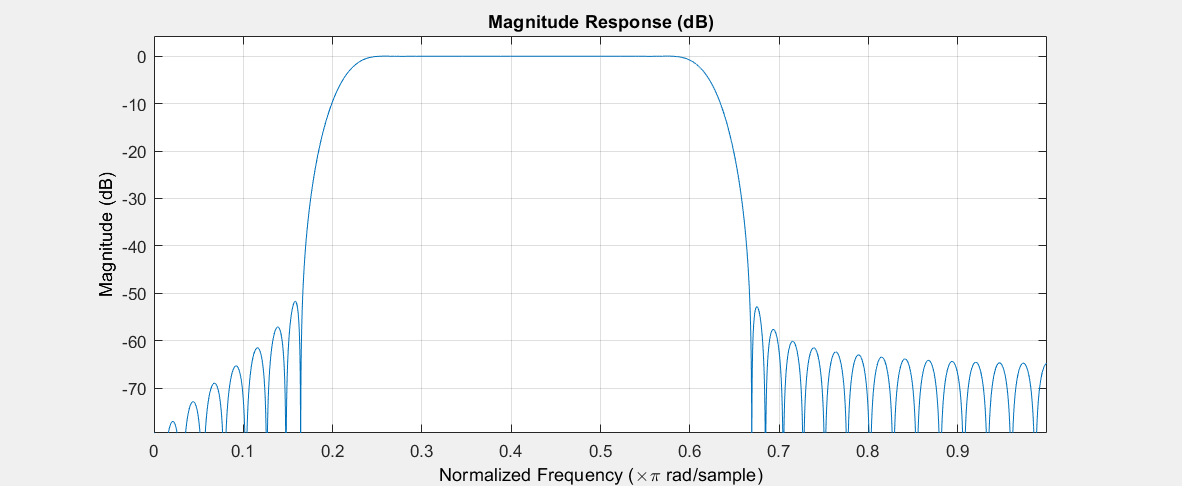

filter = hnt.*wknt; 
figure 
stem(n,filter) 
xlabel('n') 
ylabel('Amplitude') 
title(strcat('Filter Response - Kaiser Window - Time Domain')); 
grid on;

figure 
[h,w] = freqz(filter); 
w = w/T; 
h = 20*log10(abs(h)); 
plot(w,h) 
xlabel('Frequency (rad/s)') 
ylabel('Magnitude (dB)') 
title(strcat('Filter Response - Kaiser Window - Frequency Domain')); 

figure; 
n_new = 0:1:(N-1); 
stem(n_new, filter); 
title('Impulse Response of Causal Filter'); 
xlabel('n'); 
ylabel('Amplitude'); 
grid on; 

%Magnitude Response of the Filter 
fvtool(filter) %Magnitude response

### Plotting the Passband

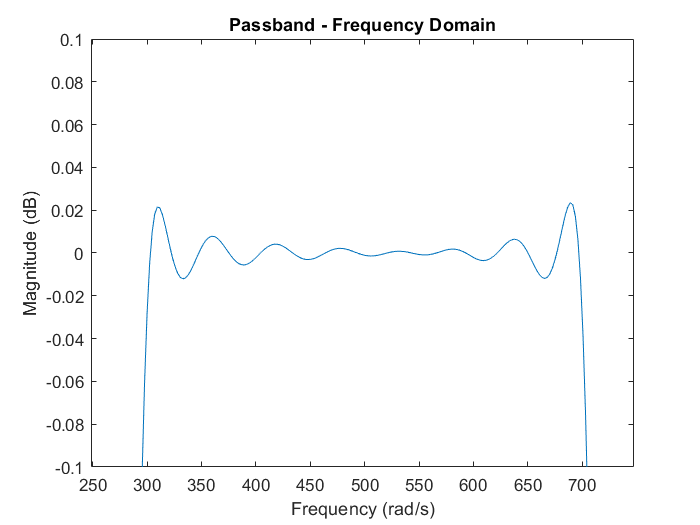

figure 
start = round(length(w)/(ws/2)*wc1); 
finish = round((length(w)/(ws/2)*wc2)); 
wpass = w(start:finish); 
hpass = (h(start:finish)); 
plot(wpass,hpass) 
axis([-inf, inf, -0.1, 0.1]); 
xlabel('Frequency (rad/s)') 
ylabel('Magnitude (dB)') 
title('Passband - Frequency Domain');

### Input, Output and Expected Signal of the Designed Filter

%Input Signal Generating 
samples = 400; 
len_fft = 2^nextpow2(samples); 

w1 = wa1/2;                                 % component frequencies of the input 
w2 = (wp2 + wp1)/2; 
w3 = (wa2 + ws/2)/2; 
wi = [w1,w2,w3]; 

nT = (0:T:samples*T); 

xnT = sin(w1*nT)+sin(w2*nT)+sin(w3*nT); 
Xw = fft(xnT, len_fft); 
X1 = T*abs(Xw(1:len_fft/2+1)); 

%Output Signal of the Designed Filter 
hnT = fft(filter,len_fft); 
Yw = hnT.*Xw; 
yt = ifft(Yw, len_fft); 
Y = T*abs(Yw(1:len_fft/2+1));

%Expected Output Signal from the Ideal Filter 
exp_ynT = sin(w2*nT); 
exp_Yw = fft(exp_ynT, len_fft); 
Y1 = T*abs(exp_Yw(1:len_fft/2+1));

### Using DFT to check the filtering

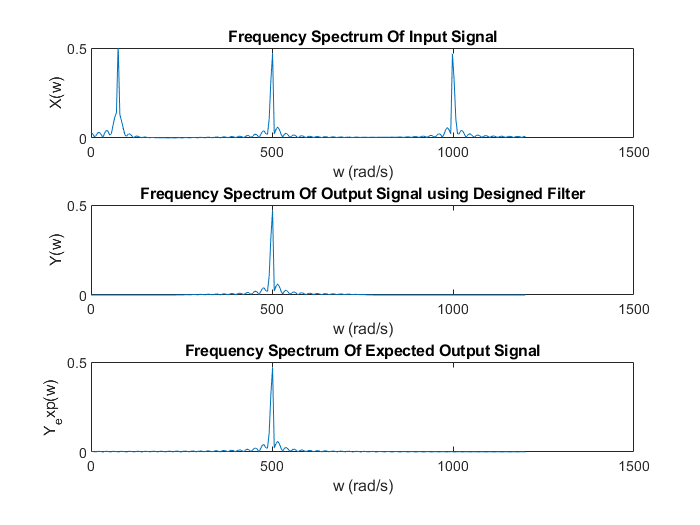

% Frequency domain representation of signals 
w = ws*(0:1/len_fft:1/2); 
figure, subplot(3, 1, 1) ; 
plot(w,X1); 
title('Frequency Spectrum Of Input Signal'); 
xlabel('w (rad/s)'); 
ylabel('X(w)'); 
axis([0, 1500, 0, 0.5]); 

subplot(3, 1, 2); 
plot(w, abs(Y')); 
title('Frequency Spectrum Of Output Signal using Designed Filter'); 
xlabel('w (rad/s)'); 
ylabel('Y(w)'); 
axis([0, 1500, 0, 0.5]); 

subplot(3, 1, 3); 
plot(w, abs(Y1')); 
title('Frequency Spectrum Of Expected Output Signal'); 
xlabel('w (rad/s)'); 
ylabel('Y_exp(w)'); 
axis([0, 1500, 0, 0.5]);

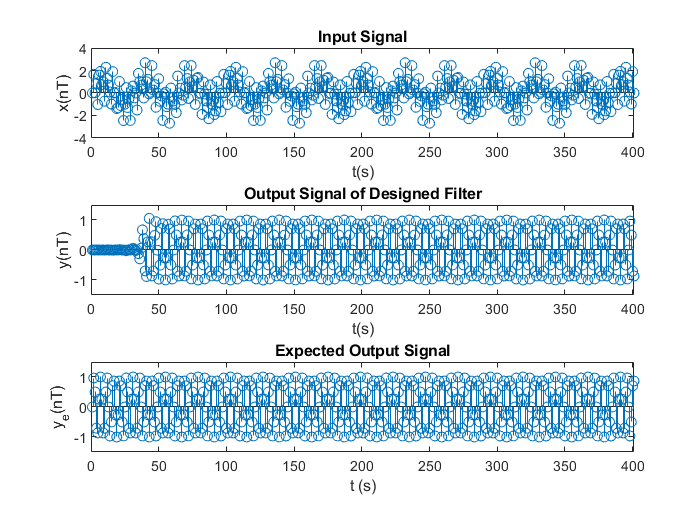


% Time domain representation of signals 
figure, subplot(3, 1, 1); 
stem(1:(samples+1),xnT(1:(samples+1))); 
title('Input Signal'); 
xlabel('t(s)'); 
ylabel('x(nT)'); 
axis([0, (samples+1), -4, 4]); 

subplot(3, 1, 2); 
stem(1:(samples+1),yt(1:(samples+1))); 
title('Output Signal of Designed Filter'); 
xlabel('t(s)'); 
ylabel('y(nT)'); 
axis([0,(samples+1), -1.5, 1.5]); 

subplot(3, 1, 3); 
stem(1:(samples+1),exp_ynT(1:(samples+1))); 
title('Expected Output Signal'); 
xlabel('t (s)'); 
ylabel('y_e(nT)'); 
axis([0, (samples+1), -1.5, 1.5]);